% ========================================================
% === SCRIPT COMPLETO: PIPELINE SVD_BC + AUTOENCODER SU ORL ===
% ========================================================
clear; clc; close all;
rng(0);
tic;

%% ----------------------------------------------------------------
%% 0) SETUP AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------
projectRoot  = pwd;  % Percorso del progetto
addpath(genpath(projectRoot));
results_path = fullfile(pwd,'results_orl_ae_svd');
if ~exist(results_path,'dir'), mkdir(results_path); end

%% ----------------------------------------------------------------
%% 1) PARAMETRI GLOBALI
%% ----------------------------------------------------------------
tol              = 1e-4;     % Tolleranza SVD_BC
maxit            = 1000;     % Iterazioni massime SVD_BC
energy_threshold = 0.95;     % Soglia energia PCA (95%)
bottleneck       = 40;       % Dimensione del codice autoencoder
epochs           = 50;       % Epoche di training AE
learning_rate    = 0.01;     % Learning rate AE
train_ratio      = 0.8;      % Frazione train/test

%% ----------------------------------------------------------------
%% 2) CARICAMENTO DATASET ORL & NORMALIZZAZIONE
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset ORL...\n');

>>> Caricamento dataset ORL...


load('dataset/volti_dataset.mat','A');  % A è [m×n]
A = double(A) / 255;                   % Normalizzazione [0,1]
[m, n] = size(A);
img_h = 112; img_w = 92;

%% ----------------------------------------------------------------
%% 3) CALCOLO VISO MEDIO & CENTRATURA
%% ----------------------------------------------------------------
mean_face  = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
A_centered = A - mean_face;

%% ----------------------------------------------------------------
%% 4) SVD_BC SU DATI CENTRATI
%% ----------------------------------------------------------------
fprintf('>>> Esecuzione SVD_BC (tol=%.1e, maxit=%d)...\n', tol, maxit);

>>> Esecuzione SVD_BC (tol=1.0e-04, maxit=1000)...


[U, S, ~] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 410x410 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=410 ... 

iter=1001 time=7.97 s
         [qr_eig] deflazione k=409 ... 

iter=1001 time=7.58 s
         [qr_eig] deflazione k=408 ... 

iter=1001 time=7.51 s
         [qr_eig] deflazione k=407 ... 

iter=1001 time=7.51 s
         [qr_eig] deflazione k=406 ... 

iter=1001 time=7.18 s
         [qr_eig] deflazione k=405 ... 

iter=1001 time=7.47 s
         [qr_eig] deflazione k=404 ... iter=611 time=4.48 s
         [qr_eig] deflazione k=403 ... 

iter=1001 time=7.32 s
         [qr_eig] deflazione k=402 ... 

iter=1001 time=7.64 s
         [qr_eig] deflazione k=401 ... 

iter=1001 time=7.33 s
         [qr_eig] deflazione k=400 ... 

iter=1001 time=7.33 s
         [qr_eig] deflazione k=399 ... 

iter=1001 time=7.33 s
         [qr_eig] deflazione k=398 ... 

iter=1001 time=7.09 s
         [qr_eig] deflazione k=397 ... 

iter=1001 time=7.21 s
         [qr_eig] deflazione k=396 ... 

iter=1001 time=7.11 s
         [qr_eig] deflazione k=395 ... 

iter=1001 time=7.35 s
         [qr_eig] deflazione k=394 ... 

iter=1001 time=6.93 s
         [qr_eig] deflazione k=393 ... 

iter=1001 time=8.29 s
         [qr_eig] deflazione k=392 ... 

iter=1001 time=6.91 s
         [qr_eig] deflazione k=391 ... 

iter=1001 time=7.13 s
         [qr_eig] deflazione k=390 ... 

iter=1001 time=6.96 s
         [qr_eig] deflazione k=389 ... 

iter=1001 time=6.81 s
         [qr_eig] deflazione k=388 ... 

iter=1001 time=6.77 s
         [qr_eig] deflazione k=387 ... 

iter=1001 time=6.87 s
         [qr_eig] deflazione k=386 ... iter=407 time=2.75 s
         [qr_eig] deflazione k=385 ... 

iter=1001 time=6.93 s
         [qr_eig] deflazione k=384 ... 

iter=1001 time=6.55 s
         [qr_eig] deflazione k=383 ... 

iter=1001 time=6.62 s
         [qr_eig] deflazione k=382 ... 

iter=1001 time=6.77 s
         [qr_eig] deflazione k=381 ... 

iter=1001 time=6.99 s
         [qr_eig] deflazione k=380 ... 

iter=1001 time=6.52 s
         [qr_eig] deflazione k=379 ... 

iter=1001 time=6.61 s
         [qr_eig] deflazione k=378 ... iter=136 time=0.90 s
         [qr_eig] deflazione k=377 ... 

iter=1001 time=6.90 s
         [qr_eig] deflazione k=376 ... 

iter=1001 time=6.58 s
         [qr_eig] deflazione k=375 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=374 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=373 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=372 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=371 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=370 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=369 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=368 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=367 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=366 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=365 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=364 ... 

iter=1001 time=6.14 s
         [qr_eig] deflazione k=363 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=362 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=361 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=360 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=359 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=358 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=357 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=356 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=355 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=354 ... iter=478 time=2.79 s
         [qr_eig] deflazione k=353 ... 

iter=1001 time=5.72 s
         [qr_eig] deflazione k=352 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=351 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=350 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=349 ... 

iter=1001 time=5.61 s
         [qr_eig] deflazione k=348 ... 

iter=1001 time=5.56 s
         [qr_eig] deflazione k=347 ... 

iter=1001 time=5.68 s
         [qr_eig] deflazione k=346 ... 

iter=1001 time=5.63 s
         [qr_eig] deflazione k=345 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=344 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=343 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=342 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=341 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=340 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=339 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=338 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=337 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=336 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=335 ... 

iter=1001 time=5.33 s
         [qr_eig] deflazione k=334 ... 

iter=1001 time=5.26 s
         [qr_eig] deflazione k=333 ... iter=39 time=0.19 s
         [qr_eig] deflazione k=332 ... 

iter=1001 time=5.35 s
         [qr_eig] deflazione k=331 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=330 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=329 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=328 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=327 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=326 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=325 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=324 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=323 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=322 ... 

iter=1001 time=5.05 s
         [qr_eig] deflazione k=321 ... 

iter=1001 time=4.87 s
         [qr_eig] deflazione k=320 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=319 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=318 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=317 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=316 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=315 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=314 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=313 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=312 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=311 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=310 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=309 ... 

iter=1001 time=5.21 s
         [qr_eig] deflazione k=308 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=307 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=306 ... iter=170 time=2.23 s
         [qr_eig] deflazione k=305 ... iter=222 time=1.18 s
         [qr_eig] deflazione k=304 ... iter=901 time=4.15 s
         [qr_eig] deflazione k=303 ... 

iter=1001 time=4.49 s
         [qr_eig] deflazione k=302 ... iter=11 time=0.05 s
         [qr_eig] deflazione k=301 ... 

iter=1001 time=4.53 s
         [qr_eig] deflazione k=300 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=299 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=298 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=297 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=296 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=295 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=294 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=293 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=292 ... iter=326 time=1.43 s
         [qr_eig] deflazione k=291 ... 

iter=1001 time=7.77 s
         [qr_eig] deflazione k=290 ... 

iter=1001 time=7.26 s
         [qr_eig] deflazione k=289 ... 

iter=1001 time=23.67 s
         [qr_eig] deflazione k=288 ... 

iter=1001 time=7.66 s
         [qr_eig] deflazione k=287 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=286 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=285 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=284 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=283 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=282 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=281 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=280 ... 

iter=1001 time=4.73 s
         [qr_eig] deflazione k=279 ... 

iter=1001 time=4.69 s
         [qr_eig] deflazione k=278 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=277 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=276 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=275 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=274 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=273 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=272 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=271 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=270 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=269 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=268 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=267 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=266 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=265 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=264 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=263 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=262 ... iter=0 time

iter=1001 time=4.14 s
         [qr_eig] deflazione k=259 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=258 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=257 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=256 ... 

iter=1001 time=3.91 s
         [qr_eig] deflazione k=255 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=254 ... 

iter=1001 time=4.02 s
         [qr_eig] deflazione k=253 ... iter=312 time=1.57 s
         [qr_eig] deflazione k=252 ... iter=626 time=2.94 s
         [qr_eig] deflazione k=251 ... 

iter=1001 time=5.87 s
         [qr_eig] deflazione k=250 ... 

iter=1001 time=5.40 s
         [qr_eig] deflazione k=249 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=248 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=247 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=246 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=245 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=244 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=243 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=242 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=241 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=240 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=239 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=238 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=237 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=236 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=235 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=234 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=233 ... 

iter=1001 time=3.63 s
         [qr_eig] deflazione k=232 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=231 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=230 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=229 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=228 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=227 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=226 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=225 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=224 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=223 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=222 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=221 ... 

iter=1001 time=3.19 s
         [qr_eig] deflazione k=220 ... 

iter=1001 time=2.99 s
         [qr_eig] deflazione k=219 ... 

iter=1001 time=3.06 s
         [qr_eig] deflazione k=218 ... 

iter=1001 time=3.05 s
         [qr_eig] deflazione k=217 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=216 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=215 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=214 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=213 ... iter=561 time=2.43 s
         [qr_eig] deflazione k=212 ... 

iter=1001 time=2.97 s
         [qr_eig] deflazione k=211 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=210 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=209 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=208 ... 

iter=1001 time=2.62 s
         [qr_eig] deflazione k=207 ... 

iter=1001 time=2.93 s
         [qr_eig] deflazione k=206 ... 

iter=1001 time=2.78 s
         [qr_eig] deflazione k=205 ... 

iter=1001 time=2.81 s
         [qr_eig] deflazione k=204 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=203 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=202 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=201 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=200 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=199 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=198 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=197 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=196 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=195 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=194 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=193 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=192 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=191 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=190 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=189 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=188 ... iter=0 time

iter=1001 time=2.19 s
         [qr_eig] deflazione k=173 ... iter=760 time=1.60 s
         [qr_eig] deflazione k=172 ... 

iter=1001 time=2.21 s
         [qr_eig] deflazione k=171 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=170 ... 

iter=1001 time=2.18 s
         [qr_eig] deflazione k=169 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=168 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=167 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=166 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=165 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=164 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=163 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=162 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=161 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=160 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=159 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=158 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=157 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=156 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=155 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=154 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=153 ... iter=0 time

iter=1001 time=0.25 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... 

iter=1001 time=0.18 s
         [qr_eig] deflazione k=48 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=47 ... iter=3 time=0.00 s
         [qr_eig] deflazione k=46 ... iter=35 time=0.01 s
         [qr_eig] deflazione k=45 ... 

iter=1001 time=0.16 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... 

iter=1001 time=0.14 s
         [qr_eig] deflazione k=41 ... iter=1 time=0.00 s
         [qr_eig] deflazione k=40 ... 

iter=1001 time=0.13 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=29 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=28 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=27 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=26 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=25 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=24 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=23 ... iter=0 time=0.00 s
         

iter=1001 time=0.02 s
         [qr_eig] deflazione k=9 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=8 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=7 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=6 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=5 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=4 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=3 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=2 ... iter=0 time=0.00 s
      [qr_eig] tutti autovalori estratti.
   [svd_BC] qr_eig completata in 448.53 s
   [svd_BC] costruisco S e U...


save(fullfile(results_path,'svd_data.mat'),'U','S');

%% ----------------------------------------------------------------
%% 5) SELEZIONE DI k TRAMITE ENERGIA CUMULATA SU σ^2
%% ----------------------------------------------------------------
sig2    = diag(S).^2;                   % Varianza spiegata
energy  = cumsum(sig2) / sum(sig2);
k       = find(energy >= energy_threshold, 1);
fprintf('>>> K = %d (%.1f%% energia)\n', k, 100*energy(k));

>>> K = 404 (96.2% energia)



%% ----------------------------------------------------------------
%% 6) PROIEZIONI PCA NORMALIZZATE [n×k]
%% ----------------------------------------------------------------
P       = U(:,1:k)' * A_centered;       % [k×n]
mu_P    = mean(P,2);                     % Media per componente
sigma_P = std(P,0,2) + eps;             % Dev. standard
P_norm  = (P - mu_P) ./ sigma_P;         % [k×n]
X_all   = P_norm';                       % [n×k]

%% ----------------------------------------------------------------
%% 7) SPLIT TRAIN/TEST per Autoencoder
%% ----------------------------------------------------------------
perm           = randperm(n);
n_train        = round(train_ratio * n);
train_idx      = perm(1:n_train);
orig_idx_test  = perm(n_train+1:end);
X_train        = X_all(train_idx, :);   % [n_train×k]
X_test         = X_all(orig_idx_test, :);% [n_test ×k]
n_test         = numel(orig_idx_test);

%% ----------------------------------------------------------------
%% 8) TRAINING AUTOENCODER SUI COEFFICIENTI PCA
%% ----------------------------------------------------------------
fprintf('>>> Training autoencoder su PCA (bottleneck=%d)...\n', bottleneck);

>>> Training autoencoder su PCA (bottleneck=40)...


[W_enc, b_enc, W_dec, b_dec, loss_history, test_loss_history] = ...
    autoencoder_train_2(X_train, X_test, mean_face, bottleneck, epochs, learning_rate);

[AE] Epoca  10/ 50: Train MSE=0.95691, Test MSE=0.98159
[AE] Epoca  20/ 50: Train MSE=0.90592, Test MSE=0.92812
[AE] Epoca  30/ 50: Train MSE=0.84740, Test MSE=0.88011
[AE] Epoca  40/ 50: Train MSE=0.74582, Test MSE=0.78941
[AE] Epoca  50/ 50: Train MSE=0.67361, Test MSE=0.69142


save(fullfile(results_path,'ae_orl_svd_weights.mat'), ...
    'W_enc','b_enc','W_dec','b_dec','loss_history','test_loss_history');

%% ----------------------------------------------------------------
%% 9) VALUTAZIONE SUL TEST SET (MSE pixel)
%% ----------------------------------------------------------------
mse_pixel = zeros(n_test,1);
for i = 1:n_test
    idx = orig_idx_test(i);
    x_in = X_all(idx, :)';                    % [k×1] normato
    h    = max(0, W_enc * x_in + b_enc);      % encoding + ReLU
    p_hat_centered = W_dec * h + b_dec;       % [k×1]
    % Denormalizzazione coeff. PCA
    p_den = p_hat_centered .* sigma_P + mu_P; % [k×1]
    % Ricostruzione pixel
    x_hat_centered = U(:,1:k) * p_den;        % [m×1] centrato
    x_rec          = x_hat_centered + mean_face; % [m×1]
    x_rec = min(max(x_rec,0),1);
    x_orig         = A(:, idx);               % [m×1]
    err            = x_orig - x_rec;
    mse_pixel(i)   = mean(err.^2);
end
mean_mse = mean(mse_pixel);
fprintf('>>> MSE medio pixel su test set: %.6f\n', mean_mse);

>>> MSE medio pixel su test set: 0.132692



mse_baseline = mean(mean((A - mean_face).^2, 1));
fprintf('MSE baseline (mean face): %.6f\n', mse_baseline);

MSE baseline (mean face): 0.026068


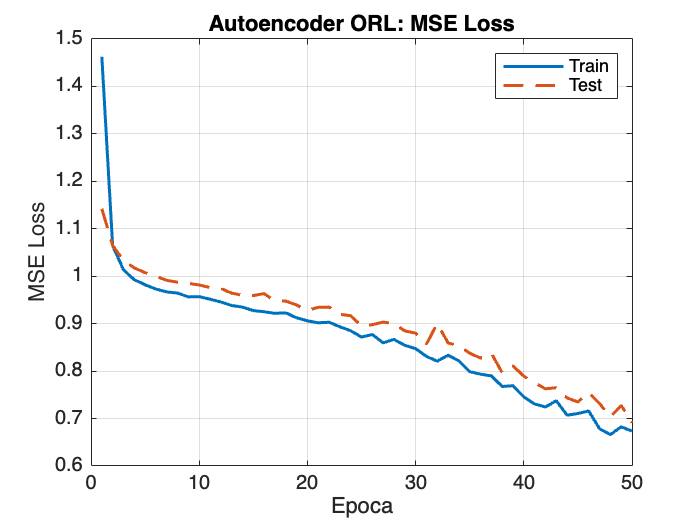



%% ----------------------------------------------------------------
%% 10) PLOT DELL’ANDAMENTO DELLA MSE LOSS
%% ----------------------------------------------------------------
figure('Name','AE ORL: Train vs Test MSE');
plot(1:epochs, loss_history,      '-','LineWidth',1.5); hold on;
plot(1:epochs, test_loss_history, '--','LineWidth',1.5);
xlabel('Epoca'); ylabel('MSE Loss');
legend('Train','Test','Location','northeast');
title('Autoencoder ORL: MSE Loss');
grid on;
saveas(gcf, fullfile(results_path,'ae_orl_loss.png'));

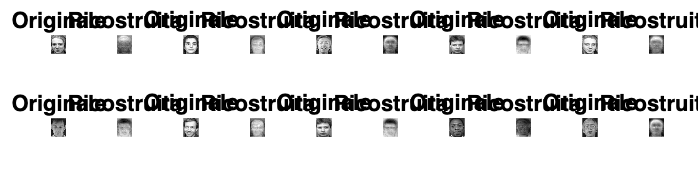


%% ----------------------------------------------------------------
%% 11) VISUALIZZAZIONE RICOSTRUZIONI (TEST)
%% ----------------------------------------------------------------
num_show = 10;
sel      = randperm(n_test, num_show);
figure('Name','AE ORL: Ricostruzioni','Position',[50,50,120*num_show,300]);
tiledlayout(2,num_show,'Padding','compact','TileSpacing','compact');
for i = 1:num_show
    idx = orig_idx_test(sel(i));
    orig_img = reshape(A(:,idx), img_h, img_w);
    x_in     = X_all(idx, :)';
    h        = max(0, W_enc * x_in + b_enc);
    p_hat    = W_dec * h + b_dec;
    % Denormalizza e ricostruisci
    rec_flat = U(:,1:k) * (p_hat .* sigma_P + mu_P) + mean_face;
    rec_img  = reshape(rec_flat, img_h, img_w);
    nexttile;
    imshow(orig_img,[]); title('Originale');
    nexttile;
    imshow(rec_img,[]); title('Ricostruita');
end
saveas(gcf, fullfile(results_path,'ae_orl_recon.png'));


fprintf('>>> Fine script (%.2f s)\n', toc);

>>> Fine script (455.59 s)
